data = load("Logi\Second_try.mat");
Second_try = data.Second_try;


start = 144;
end_vec = 2000;
t = 0:0.01:18.56

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


acc = Second_try.Var29(start:end_vec)/2048;
acc_y = Second_try.Var28(start:end_vec)/2048;
acc_x = Second_try.Var27(start:end_vec)/2048;

acc_total = sqrt(acc.^2 + acc_y.^2 + acc_x.^2)

acc_total =     0.9887
    0.9878
    0.9904
    0.9952
    1.0026
    1.0045
    1.0078
    1.0038
    0.9964
    0.9905
    0.9861
    0.9882
    0.9952
    0.9977
    1.0050


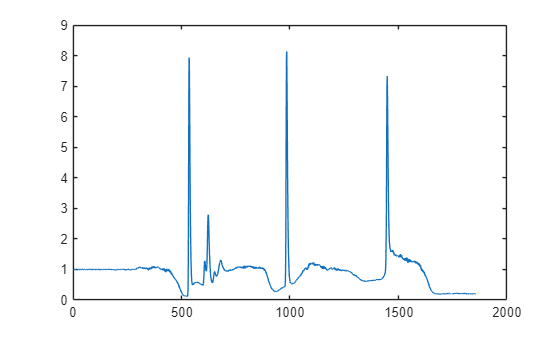


plot(acc)

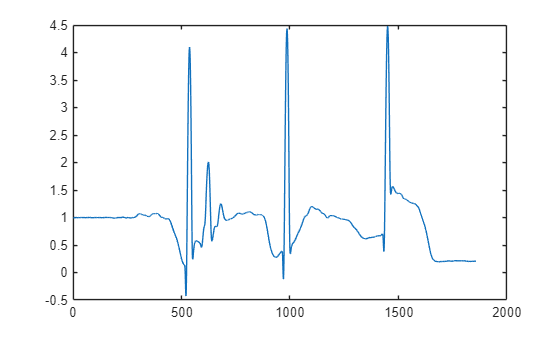

test = smoothdata(acc, "sgolay", 31, "Degree", 2);
plot(test)

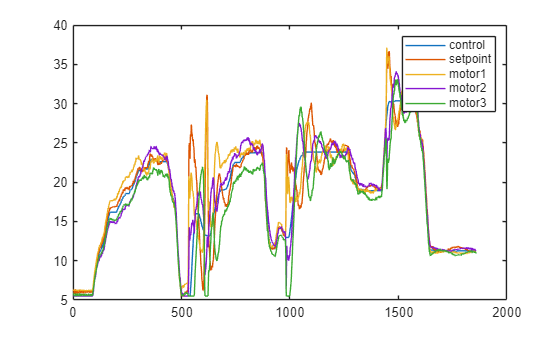

control = Second_try.Var15(start:end_vec);
setpt = 5.5 + (Second_try.Var19(start:end_vec) / 1000) * (100 - 5.5);
eng_1 = (Second_try.Var30(start:end_vec) - 48) / (2047 - 48) * 100;
eng_2 = (Second_try.Var31(start:end_vec) - 48) / (2047 - 48) * 100;
eng_3 = (Second_try.Var32(start:end_vec) - 48) / (2047 - 48) * 100;
eng_4 = (Second_try.Var33(start:end_vec) - 48) / (2047 - 48) * 100;

eng_sum = (eng_1 + eng_2 + eng_3 + eng_4)/4;
% plot(control)
plot(setpt)
hold on
plot(eng_1)
plot(eng_2)
plot(eng_3)
plot(eng_4)
hold off
legend("control", "setpoint", "motor1", "motor2", "motor3", "motor4")

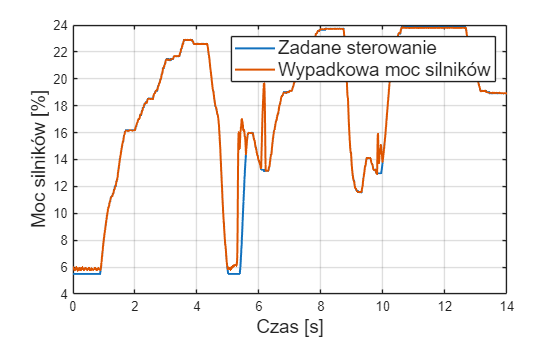

plot(t, setpt, 'LineWidth', 1.5)
hold on
plot(t, eng_sum, 'LineWidth', 1.5)
xlim([0 18])
hold off
grid on
legend("Zadane sterowanie", "Wypadkowa moc silników", 'FontSize', 14)
ylabel('Moc silników [%]', 'FontSize', 14);
xlabel('Czas [s]', 'FontSize', 14);
xlim([0 14])

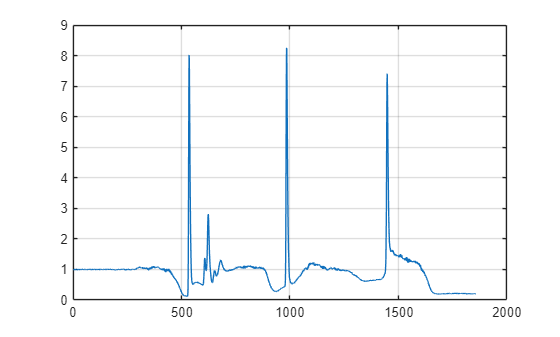




plot(acc_total)
grid on

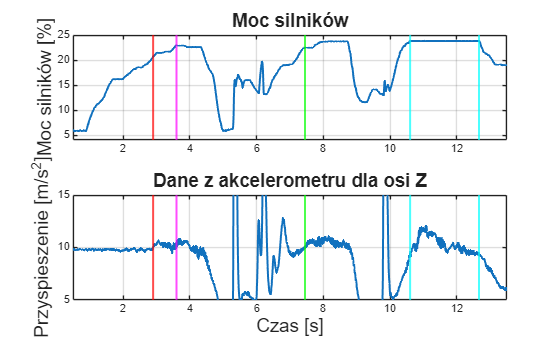

figure;

subplot(2,1,1)
plot(t, eng_sum, 'LineWidth', 1.5);
grid on;
ylabel('Moc silników [%]', 'FontSize', 14);
title('Moc silników', 'FontSize', 14);
xline(2.9, 'r', 'LineWidth', 1.5)
xline(3.6, 'm', 'LineWidth', 1.5)
xline(7.45, 'g', 'LineWidth', 1.5)
xline(10.6, 'c', 'LineWidth', 1.5)
xline(12.66, 'c', 'LineWidth', 1.5)
xlim([0.5 13.5])
ylim([4 25])

subplot(2,1,2)
plot(t, acc*9.81, 'LineWidth', 1.5);
grid on;
xlabel('Czas [s]', 'FontSize', 14);
ylabel('Przyspieszenie [m/s^2]', 'FontSize', 14);
title('Dane z akcelerometru dla osi Z', 'FontSize', 14);
xline(2.9, 'r', 'LineWidth', 1.5)
xline(3.6, 'm', 'LineWidth', 1.5)
xline(7.45, 'g', 'LineWidth', 1.5)
xline(10.6, 'c', 'LineWidth', 1.5)
xline(12.66, 'c', 'LineWidth', 1.5)
xlim([0.5 13.5])
ylim([5 15])

control_cal = (control-1000)*0.04

control_cal =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


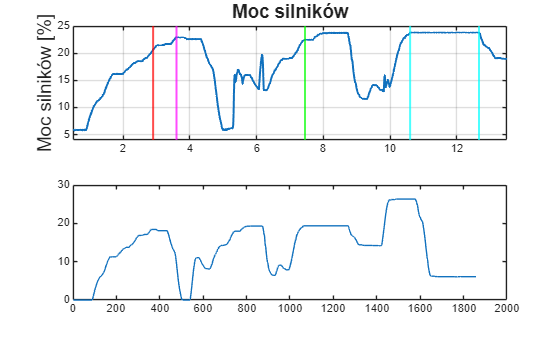

plot(control_cal)

control_cal_normal = control_cal/100;

% fig = figure;
% ax = axes(fig);
% 
% yyaxis(ax, 'left')
% p1 = plot(ax, t, eng_sum, 'LineWidth', 1.5);
% ylabel(ax, 'Sterowanie [%]');
% 
% yyaxis(ax, 'right')
% p2 = plot(ax, t, acc_total, 'LineWidth', 1.5);
% ylabel(ax, 'Przyspieszenie [m/s^2]');
% 
% xlabel(ax, 'Czas [s]');
% grid(ax, 'on');
% 
% legend(ax, [p1 p2], ...
%     {'Sterowanie', 'Przyspieszenie'}, ...
%     'Location', 'best');
% 
% title(ax, 'Sterowanie oraz odpowiedź układu');

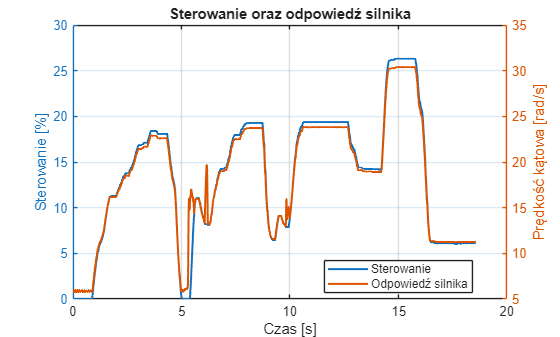

figure;

yyaxis left
plot(t, control_cal, 'LineWidth', 1.5);
ylabel('Sterowanie [%]');

yyaxis right
plot(t, eng_sum, 'LineWidth', 1.5);
ylabel('Prędkość kątowa [rad/s]');

grid on;
xlabel('Czas [s]');

legend('Sterowanie', 'Odpowiedź silnika', 'Location', 'best');
title('Sterowanie oraz odpowiedź silnika');

% Dla Ix
Kpp = 0.0658

Kpp = 0.0658

Kip = 1.2330

Kip = 1.2330


% Dla Iz
% Kpp = 0.1363
% Kip = 2.5560

Ix = 1.37e-3;       % moment bezwładności względem OX [kg*m^2]
% Ix = 2.84e-3          % moment bezwładności względem OZ [kg*m^2]

num = [
    Kpp/Ix, ...
    Kip/Ix
];

den = [
    1, ...
    Kpp/Ix, ...
    Kip/Ix
];

Gpc = tf(num, den)


Gpc =
 
     48.03 s + 900
  -------------------
  s^2 + 48.03 s + 900
 
Continuous-time transfer function.


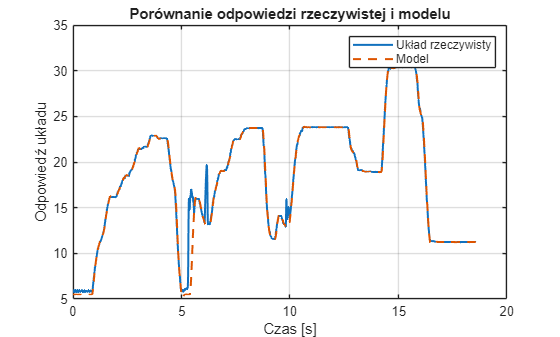


y_model = lsim(Gpc, control_cal, t);

figure;

plot(t, eng_sum, 'LineWidth', 1.5);
hold on;

plot(t, y_model*(100 - 5.5)/100+5.5, '--', 'LineWidth', 1.5);

grid on;
xlabel('Czas [s]');
ylabel('Odpowiedź układu');
legend('Układ rzeczywisty', 'Model');
title('Porównanie odpowiedzi rzeczywistej i modelu');
hold off